% Ethan MacDonald 
% 8/10/18
% Problems from: MATH241H textbook, page 9-10, .pdf page 20.

% (a) Graph of f(x) = x^3 - 4x^2 + 1
disp("(a) Graph of f(x) = x^3 - 4x^2 + 1")

(a) Graph of f(x) = x^3 - 4x^2 + 1


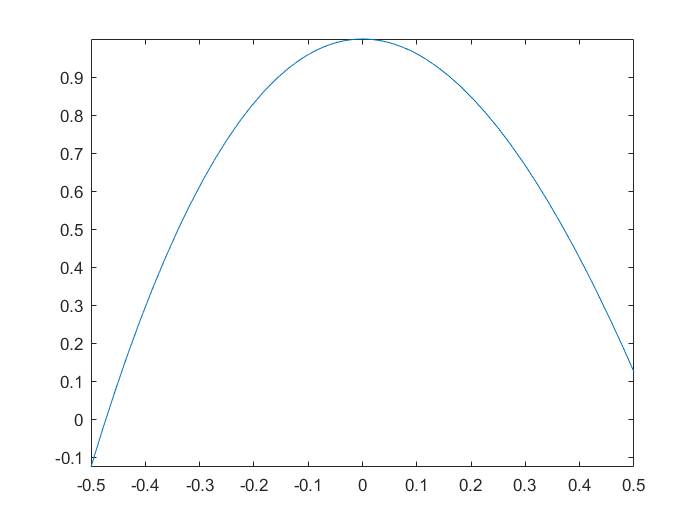

f = @(x) x.^3 - 4*x.^2 + 1;
fplot(f,[-1/2 1/2])


% (b) Symbolic exact values of x where the graph crosses the x-axis
disp("(b) Symbolic exact values of x where the graph crosses the x-axis")

(b) Symbolic exact values of x where the graph crosses the x-axis


syms x
fsym = x.^3 - 4*x.^2 + 1;
solve(x.^3 - 4*x.^2 + 1 ==0, x, 'MaxDegree',3)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{16}{9\,\sigma_{2}}+\sigma_{2}+\frac{4}{3}\\ \frac{4}{3}-\frac{\sigma_{2}}{2}-\frac{8}{9\,\sigma_{2}}-\sigma_{1}\\ \frac{4}{3}-\frac{\sigma_{2}}{2}-\frac{8}{9\,\sigma_{2}}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{16}{9\,\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\frac{101}{54}+\frac{\sqrt{108}\,\sqrt{229}\,\mathrm{i}}{108}\right)}^{1/3} \end{array}$$


% (c) Converted values from part b to numerical values with double
disp("(c) Converted values from part b to numerical values with double")

(c) Converted values from part b to numerical values with double


rts = solve(x.^3 - 4*x.^2 + 1 ==0, x, 'MaxDegree',3);
roots = double(rts)

roots =     3.9354
   -0.4728
    0.5374


rt3 = fzero(f,3)

rt3 = 3.9354

rt2 = fzero(f,-.5)

rt2 = -0.4728

rt1 = fzero(f,.5)

rt1 = 0.5374

disp("The roots given from using double and fzero are identical to four decimal places")

The roots given from using double and fzero are identical to four decimal places



% (d) Soliving the integral of f(x) from -.4728 to .5374
% fplot(f,[-1/2 4])
disp("(d) Soliving the integral of f(x) from -.4728 to .5374")

(d) Soliving the integral of f(x) from -.4728 to .5374


exactInt = int(f,x,rt2,rt1)

$$exactInt = \frac{52975127434342184277007248918021740401691333019047371747664699555}{78984218751417890023438520762752824239171321550411833440733233152}$$

area = double(exactInt)

area = 0.6707

disp("This answer is resonable because it is a positive area that is less than one, and this is what" + ...
    " is expectied from the graph in part (a), a less than one area above the x-axis")

This answer is resonable because it is a positive area that is less than one, and this is what is expectied from the graph in part (a), a less than one area above the x-axis



% (e) Where f(x) is increasing and decreasing. Where are the relative max. and min. points of f.
disp("Where f(x) is increasing and decreasing. Where are the relative max. and min. points of f.")

Where f(x) is increasing and decreasing. Where are the relative max. and min. points of f.


f_prime = diff(f,x)

$$f\_prime = 3\,x^{2}-8\,x$$

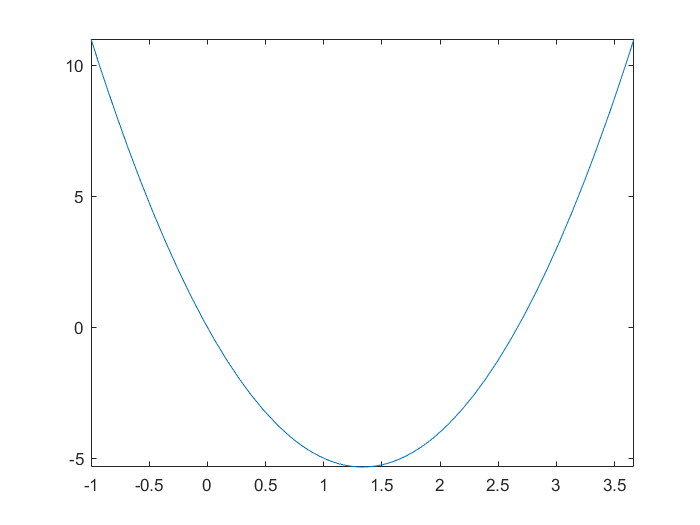

fplot(f_prime,[-1 3.66666])

f_primeRts = solve(f_prime,x)

$$f\_primeRts = \left(\begin{array}{c} 0\\ \frac{8}{3} \end{array}\right)$$

f_primeRoots = double(f_primeRts)

f_primeRoots =          0
    2.6667


disp("Becasue f' is positive when x<0 and x>8/3, f is increasing when x<0 and x>8/3")

Becasue f' is positive when x<0 and x>8/3, f is increasing when x<0 and x>8/3


disp("Becasue f' is negative when 0<x<8/3, f is decreasing when 0<x<8/3")

Becasue f' is negative when 0<x<8/3, f is decreasing when 0<x<8/3


extrema = vpa(solve(f_prime ==0,x), 6)

$$extrema = \left(\begin{array}{c} 0\\ 2.66667 \end{array}\right)$$

disp("0 is a relative max becasue f' goes from positive to negative." + ... 
" 8/3 is a relative min because f' goes from negative to positive.")

0 is a relative max becasue f' goes from positive to negative. 8/3 is a relative min because f' goes from negative to positive.


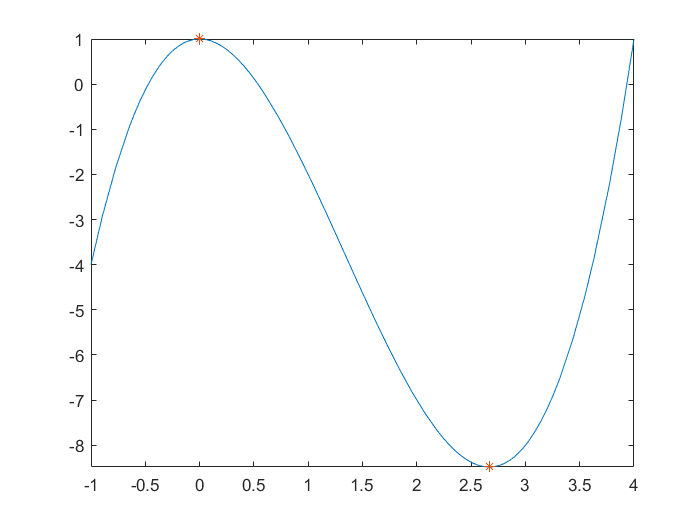

fplot(f,[-1 4])
hold on
plot(extrema, subs(fsym,extrema), '*')
hold off


% (f) Finding coords of relative max and min points of f.
disp("(f) Finding coords of relative max and min points of f.")

(f) Finding coords of relative max and min points of f.


fMax = f(0); disp("max: (0, " + fMax + ")")

max: (0, 1)


fMin = f(8/3); disp("min: (8/3, " + fMin + ")")

min: (8/3, -8.4815)


% fExtreama = f(extrema)

% (g) Finding concavity of f.
disp("(g) Finding concavity of f.")

(g) Finding concavity of f.


f_dprime = diff(f_prime,x)

$$f\_dprime = 6\,x-8$$

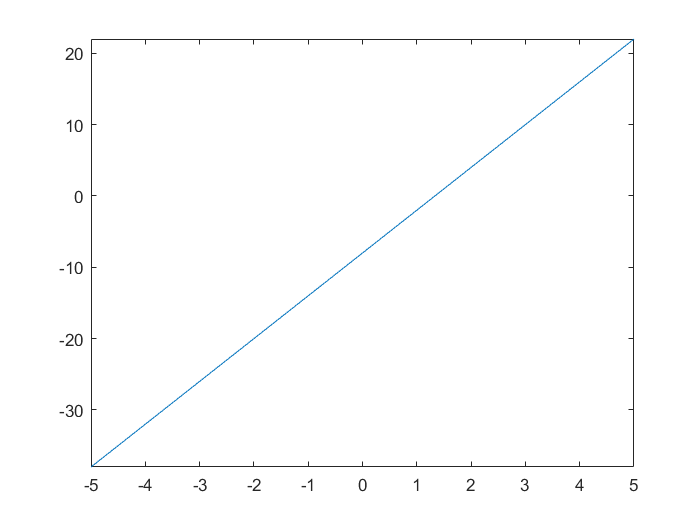

fplot(f_dprime)

symInflectionPoints = solve(f_dprime == 0,x)

$$symInflectionPoints = \frac{4}{3}$$

inflectionPoints = double(symInflectionPoints)

inflectionPoints = 1.3333

disp("f is concave down where x<4/3 because f'' is negative when x<4/3")

f is concave down where x<4/3 because f'' is negative when x<4/3


disp("f is concave up where x>4/3 becaseu f'' is positive when x>4/3")

f is concave up where x>4/3 becaseu f'' is positive when x>4/3



%Conclusion
disp("Final graph")

Final graph


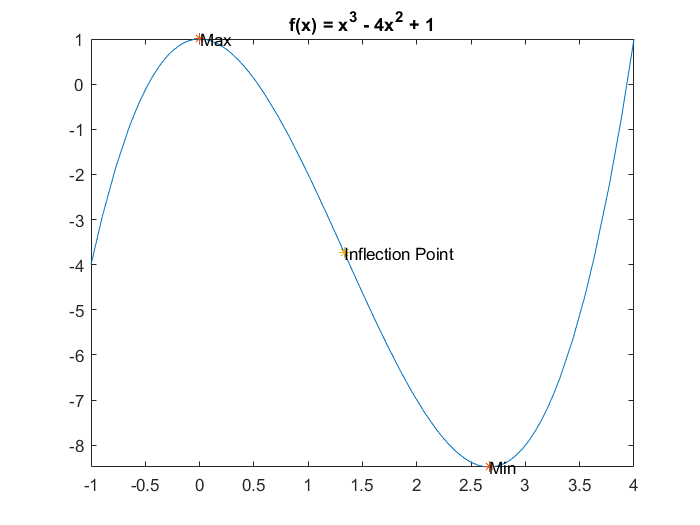

fplot(f,[-1 4])
hold on
title('f(x) = x^3 - 4x^2 + 1')
plot(extrema, subs(fsym,extrema), '*')
text(0,1,"Max")
text(8/3,-8.4815, "Min")
plot(inflectionPoints, f(inflectionPoints), '*')
text(4/3,f(4/3), "Inflection Point")
hold off